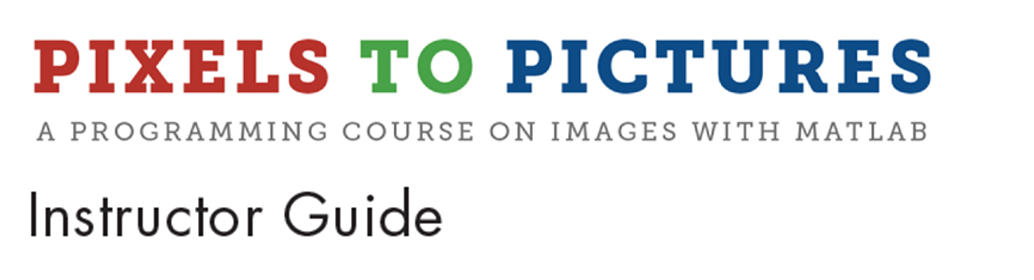

# Module 8: Applying Color Filters to Images

**Prerequisite Domain Knowledge:** Functions, MATLAB Syntax, Matrices

**Expected Completion Time: **60 minutes

## Applying Color Filters to Real Pictures

*Expected Duration: 10 minutes*

### Learning Objectives

- Achieve color filter effect on a picture by adding transparent color sheet on top of it and looking at both together.

### Materials

- Some printed images from the "Image Library" folder within ***instructor_resources***

- Transparent color gel sheets

### **Steps**

Tell students that they will now learn some real world application of filter.  Ask: 

- *Has anyone ever applied different color filters on their images on phones?  *

-     Students may mention using filters on phone apps like Instagram, Facebook, Snapchat, etc.

- *How do you think the filters get applied to the images? *

-     Give them a couple of minutes to think about this.  Accept all reasonable answers.

Gather the students around the table with the images and the color gel sheets.

Hold up one of the scenery pictures in one of your hands. 

Hold up the red transparent color sheet in your other hand. 

Place the color sheet on top of the scenery picture. The picture now has a red filter. 

Give the students 5 mins to apply different colored sheets on different images and observe how a color filter effect gets applied on the images. Ask:

- *What happens to the image each time we place a color sheet over it?  *

-     Students should notice that each time the picture has a different color filter. So it looks like we need to ***ADD*** the color sheet on top of the picture to get a filter image of our choice. 

- *What does this mean in MATLAB?  *

-     Accept all reasonable answers.  Students may mention that a color filter may involve adding an RGB layer to the image.  

Explain to the students that we know a picture is rectangular shaped in real life, which translates to a matrix in MATLAB that has several rows and columns. It appears from the color sheets that the filter has three characteristics:

- It is also rectangular like the picture

- It is the same size as the picture

- It has just one color throughout.

In MATLAB, this translates as, the filter:

- Is also a matrix with rows and columns like the digital image.

- Has the same size, i.e. the same numbers of rows and columns as the image.

- Has the same RGB value for every pixel. 

Let's go into MATLAB and try this out.  

## Performing Matrix Calculations in MATLAB

*Expected Duration: 20 minutes*

### Learning Objectives

- Learn how to add, subtract and multiply matrices in MATLAB.

    Before we can add color filters to images, we first need to learn how to do calculations with matrices. We can then apply that to creating filters and adding them to images.

### Materials

- MATLAB®

- Worksheet "Matrix Calculations"

### **Steps**

Tell students that before we can add color filters to images, we first need to learn how to do calculations with matrices.  We can then apply that to creating filters and adding them to images.

Guide students to use the following commands in the Command Window, type `clc, clear, close all` to clean up. This may be a good time to check that the students understand what each of these commands do.

Then create a new matrix:

Remind the students that a space between numbers places them next to each other and a semi-colon places them on the next line.  Ask:

- *How might we be able to create a matrix in which each value is 10 greater than the values in matrix A?  *

-     Allow students to think about what this means conceptually and how to possible write a command for this.

Guide the students through creating a variable B that adds 10 to A. 

The number 10 gets added to each number in matrix A. So when we add a single value to a matrix, it gets added to each number in the matrix.  Ask:

- *How might we create a matrix, C, that multiplies A by 3?  *

-     Allow students to think about what this means conceptually and how to write a command for this.  Similarly, multiplying one value with a matrix, multiplies it with each number in the matrix.

- *How might we create a matrix, D, that adds matrices B and C?*

-     Allow students to think about what this means conceptually and how to write a command for this.  Students should realize that this would be similar to adding variables that contain just one number.

        Explain to students that in this case, each number in matrix C gets added to the corresponding number in matrix B. So it’s an element-wise addition.

- *How might we create a matrix, E, that multplies matrices B and C? (Optional) *

-     Allow students to think about what this means conceptually and how to write a command for this.  Students should realize that this would be similar to multiplying variables that contain just one number.      

Note that the syntax for element-wise multiplication is dot-asterix (.*) and not just asterisk. This is because MATLAB does matrix multiplication according to the rules of linear algebra when used only with asterisk. Let the students know that linear algebra is something that is taught in engineering universities and it won’t be covered in this class. So they only concentrate on element-wise multiplication using the *dot-asterisk notation*. 

Instruct students to create a new matrix as follows:

Have students try adding or multiplying this new matrix to A. Ask:

- *What they think will happen? *

-     Students should notice that this will give an error. In element-wise addition or multiplication, it is very important that the number of elements in each matrix matches otherwise the unmatched values will give an error.

Distribute the **Matrix Calculations** worksheet among the students.

 
web('worksheets_and_handouts/MatrixCalculations.pdf', '-browser');

Ask them to complete the worksheet by doing the calculations by hand and then using MATLAB to verify their results. This will give them some practice in creating matrices and using them in calculations.

## Adding Color Filters to Images Using MATLAB

*Expected Duration: 30 minutes*

### Learning Objectives

- Algorithm development

- Addition of matrices

Every activity that we want to achieve on a computer can be broken down into several basic steps or single line commands. This set of steps that the computer executes is called an algorithm or a program. In other words, when we want the computer to do something for us we develop an algorithm/program, which lists out all the basic steps the computer needs to take to complete the action. Going forward, we are going to start thinking of every activity in MATLAB as a list of sequential steps that the computer can execute and write programs accordingly. 

### Materials

- MATLAB®

- Handout "RGB Color Table"

- Handout "MATLAB Functions"

### **Steps**

Tell students that every activity that we want to achieve on a computer can be broken down into several basic steps or single line commands. This set of steps that the computer executes is called an algorithm or a program. In other words, when we want the computer to do something for us we develop an algorithm/program, which lists out all the basic steps the computer needs to take to complete the action. Going forward, we are going to start thinking of every activity in MATLAB as a list of sequential steps that the computer can execute and write programs accordingly.

Tell the students to think back to the special effects activities, especially the `CustomEffects.mlx` script. 

 
open 'CustomEffects.mlx'

Here, the algorithm steps were as follows:

- Clean up everything

- Read in image

- View image

- Apply pincushion effect on image

- Apply neon effect to that

- View final image

So, without even realizing it they have started developing algorithms that the computer can understand. 

Applying the same thought process to the activity at hand – adding color filters to images – ask:

- *What they think are the steps the computer needs to execute to complete the task successfully? *

If they are having trouble, prompt them with the list of steps below. To add color filters to images, MATLAB needs to:

- Read in an input image

- View input image

- Create color filter

- View color filter

- Add filter to image

- View image with color filter

Write these steps out on the board or flipchart as they are discussing the steps needed. 

In the Command Window, ask the students to type out:

 
open 'AddColorFilter.mlx'

This should open up a script with a few lines of code. Ask the students to look at the heading of each section and verify that they are the same as the steps listed out on the board. 

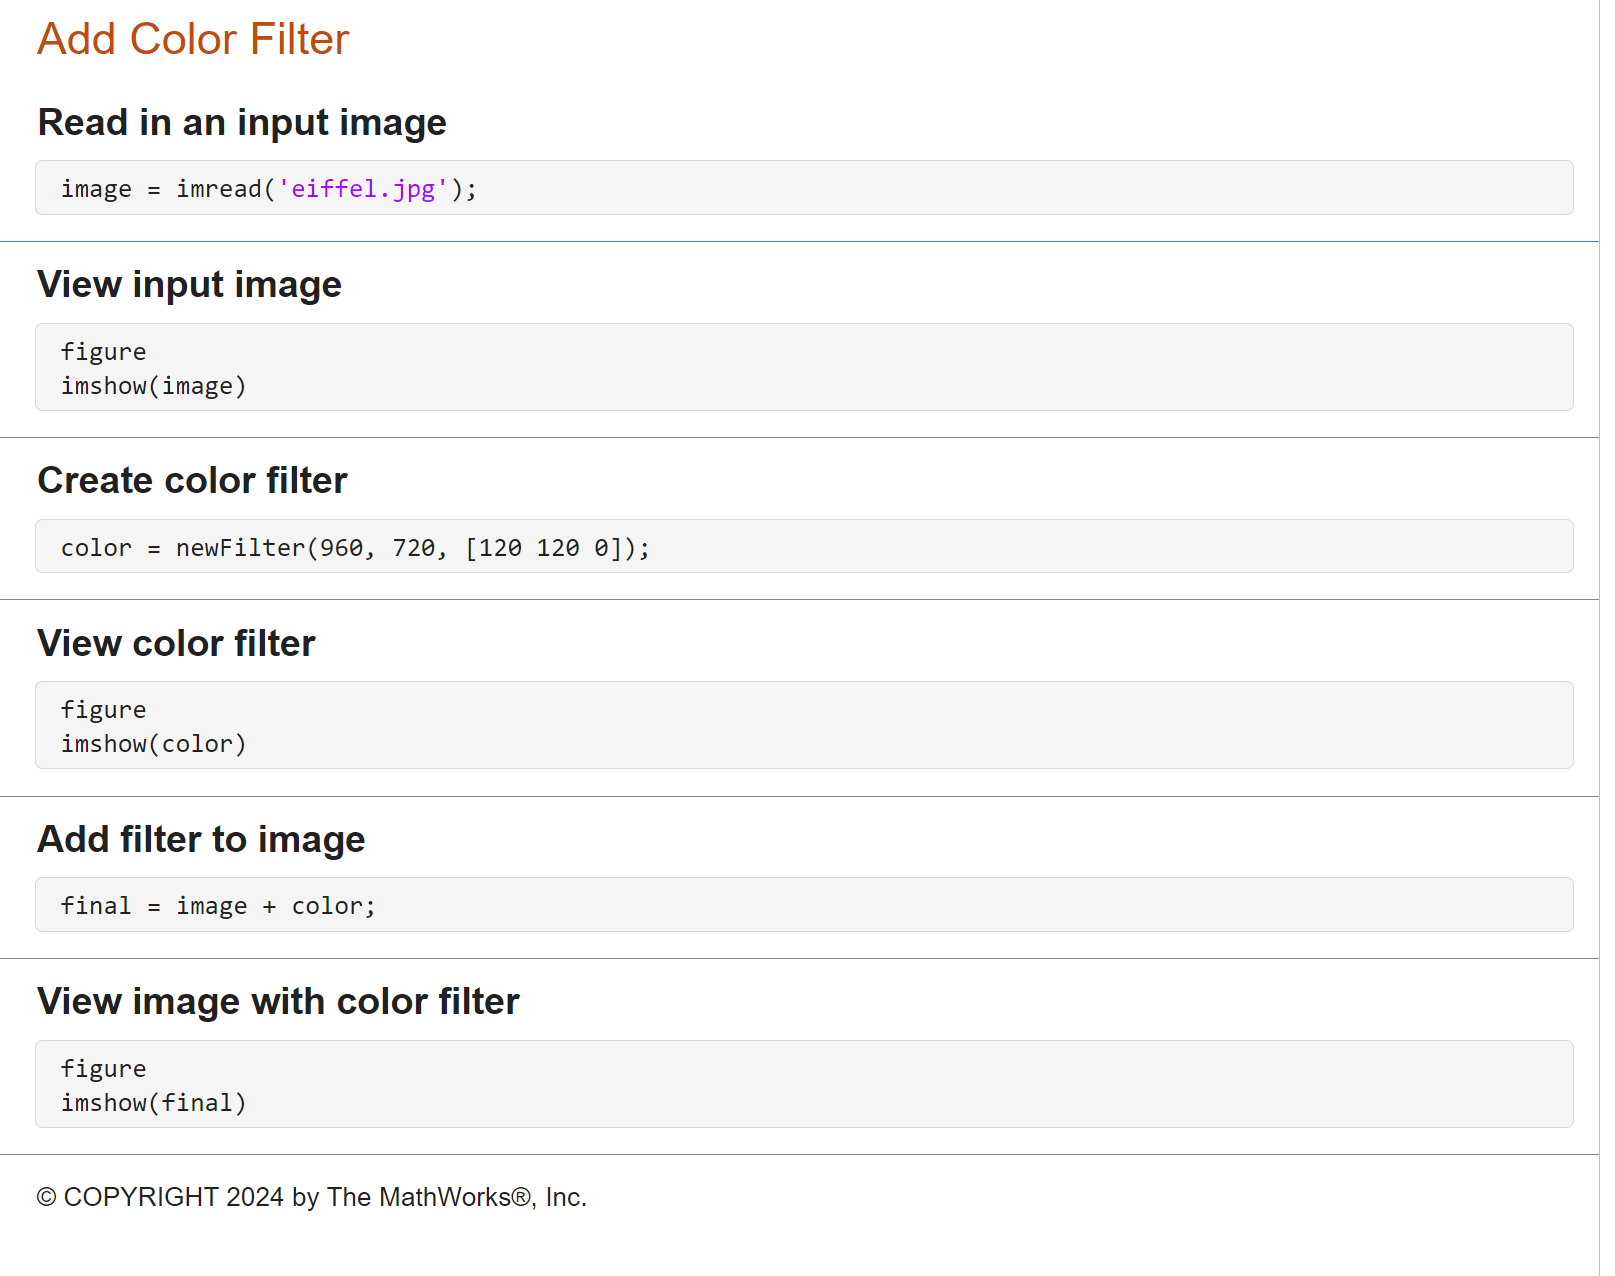

In the Command Window, type in `clc, clear,` and `close all` to clean up before running this script.

Click on **Run **in the **Editor tab**. This should give the following results:

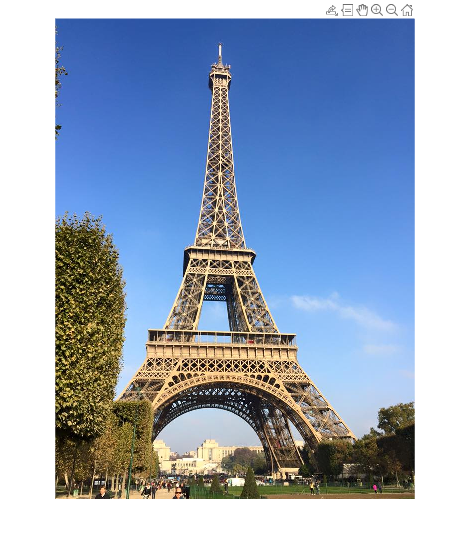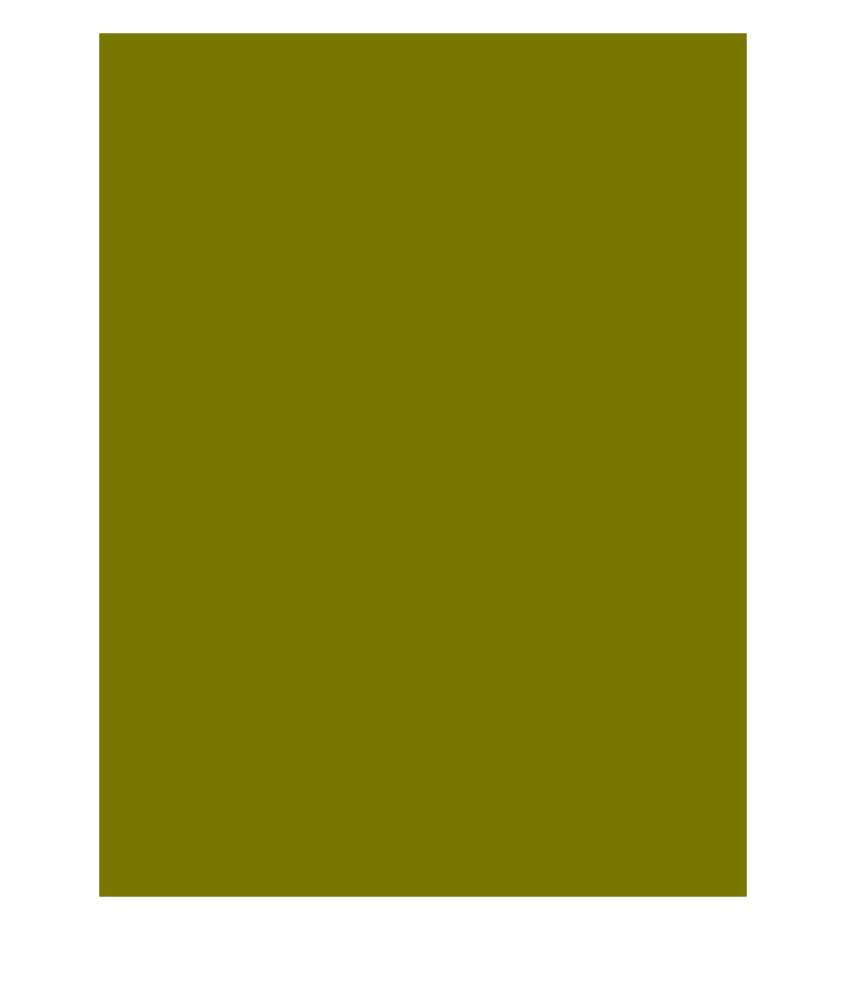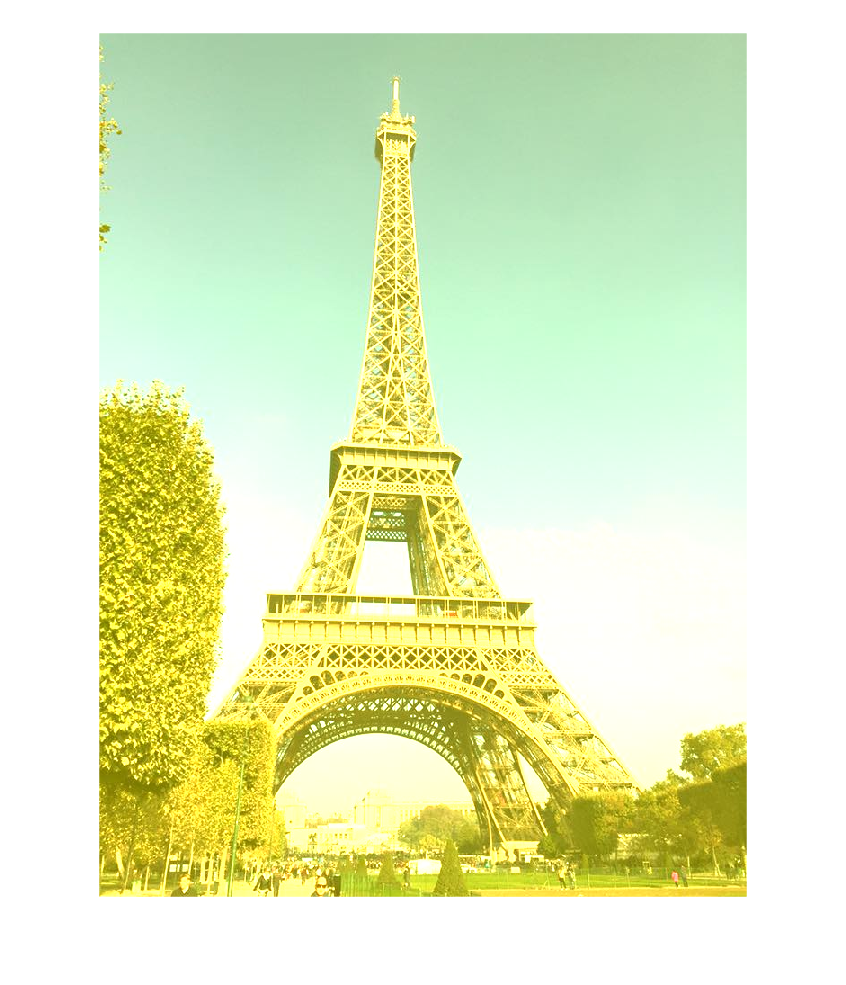

Now that they have seen what the script is doing, ask the students if they recognize all the functions being used in the script. This is a good place to verify they are following along by asking them questions like:

- **What does line 1 do?** 

- *    Ans: reads in an image.*

- **What do lines 2 and 3 do?** 

- *    Ans: creates a new figure and displays the image*

- **What does line 7 do?** 

- *    Ans: adds the image matrix to the color matrix.*

Students should be able to identify that they don’t know the `newFilter` function used in line 4.

Ask them what the 3 inputs to the function are:

- **Input 1** – the number of rows we want the color filter to have

- **Input 2** – the number of columns we want the filter to have

- **Input 3** – the color we want the filter to have using R-G-B values

So line 4 is creating a color filter with 960 rows, 720 columns and R = 120, G = 120, B = 0.

Ask the students why is the filter being created with 960 rows and 720 columns. If they are having trouble answering, point their attention to the **Workspace** and ask them to check out the size of the image

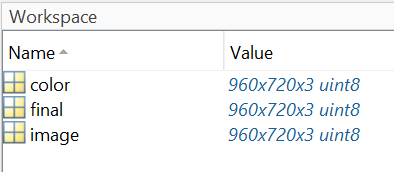

Remind them that for matrix addition to work, the size of the two matrices need to be the same. So we create a color filter that has the same number of rows and columns as the image. 

Students can now change the color of the filter in the script (by changing the RGB values – the third input) and run the script each time to view the changes. Ask them to try this a few times. They can use the **RGB Color Table Handout **to choose different filter colors.

 
web('worksheets_and_handouts/RGBColorTable.pdf', '-browser');

Change the input image to ‘mountains.jpg’ as shown below and ask the students to try and run the script. 

 Ask: 

- *Does it work?  Why or why not? *

-     No. Ask them why they think it failed. The Command Window will show the error message as follows:

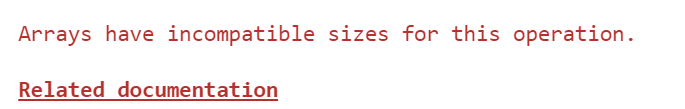

Looking at the error message we can see the error happens when trying to add the two matrices and MATLAB is complaining about array dimensions not matching. Have them look at the Workspace.

Ask: 

- *What does the information in the Workspace tell us the issue is? *

-     Students should remember that in Matrix addition the two matrices should have the same number of rows and columns to successfully do element-wise addition. Here the size of the two matrices are different and hence the addition is failing. 

- *What might be a solution for this issue?  *

-     Allow students to share their ideas.

Discuss these three solutions:

- *Change the size of the color filter to match the image*

-     This will fix the issue only for this image but they will encounter the same problem if they read in another different image which has different dimensions (rows and columns).  

- *Change the size of the image to match the color filter * 

-     Ask the students to look at the **MATLAB Functions Handout **and see if they can find any function that can help them resize an image – `imresize`. 

 
web('worksheets_and_handouts/MATLABFunctions.pdf', '-browser');

We can use `imresize` to resize the input image to be a chosen number of rows and columns (e.g. 500 rows and 500 columns) and create a color filter with the same number of rows and columns. This will ensure the script will work for different images. However, by resizing the images we may be distorting the original aspect ratio of the image.

- *Find the size of the image and resize the filter to be the same size as the image *

- *    We can use the *`size`* function to find the size of the input image. This returns the number of rows, columns and pages the image has as a row vector. Then we can extract the row and column values by using indexing and use them as inputs to *`newFilter`*. So every time a new image is read in, the size of the filter will automaticatically adjust to match the size of the image.*

 Once the size issue is fixed, the script is ready to the executed. 

Tell students that some of the color filters applied maybe too intense. For example, the yellow filter shown below.

 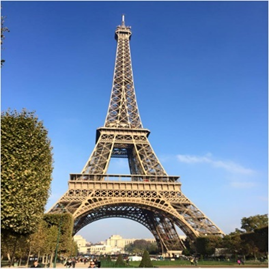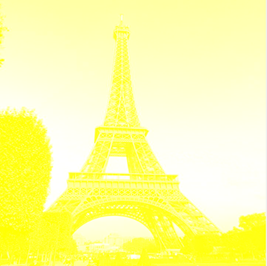

This can be rectified by multiplying all the values in the filter with an intensity factor ranging from 0 to 1

 

Give the students 5-10 minutes to bring in different images and apply different color filters of varying intensities.

At the end of this experimenting time, ask:

- *What interesting things have you learned about color filters?  *

-     Accept all reasonable responses from the students.

- *What are some things that you should keep in mind when using color filters?  *

-     Accept all reasonable answers.  Students may mention things like controlling the intensity of the color filter.

© COPYRIGHT 2024 by The MathWorks®, Inc.